clear all
close all
clc

**3. Variáveis e distribuições aleatórias**

1. Considere a vari´avel aleatória X correspondente a face que fica para cima no lançamento de 1 dado. Usando os valores teoricos: 

(a) Produza um gráfico, em Matlab, que represente a funcao massa de probabilidade1 de X; 

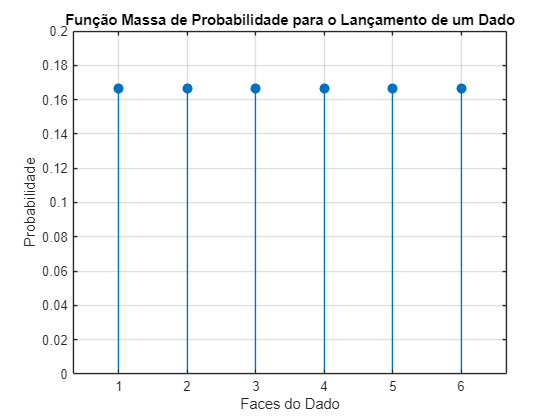

% Valores possíveis para o dado
x = 1:6; % Faces do dado

% Probabilidades para cada face
p = repmat(1/6, 1, 6); % Probabilidade igual para cada face

% Calcular a função de distribuição acumulada (CDF)
F = cumsum(p); % Soma acumulada das probabilidades

% Criar a figura
figure;

% Gráfico da função massa de probabilidade
stem(x, p, 'filled', 'MarkerSize', 7);
xlabel('Faces do Dado');
ylabel('Probabilidade');
title('Função Massa de Probabilidade para o Lançamento de um Dado');
xticks(x);
ylim([0 0.2]);
grid on;

(b) Num segundo grafico da mesma figura, desenhe o grafico da funcao de distribuicão acumulada (use a funcão stairs do Matlab).

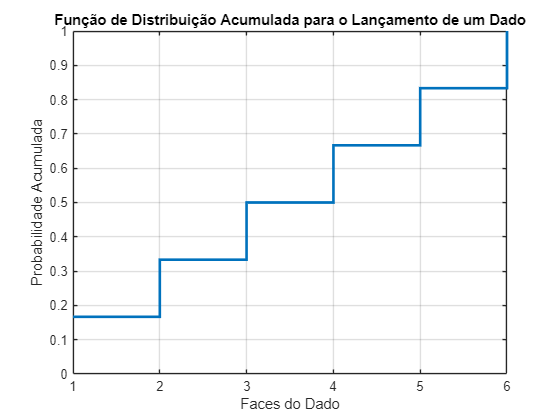

figure;
% Gráfico da função de distribuição acumulada
stairs(x, F, 'LineWidth', 2);
xlabel('Faces do Dado');
ylabel('Probabilidade Acumulada');
title('Função de Distribuição Acumulada para o Lançamento de um Dado');
xticks(x);
ylim([0 1]);
grid on;

2. Considere uma caixa contendo 90 notas de 5 Euros, 9 notas de 50 e 1 de 100. 

(a) Descreva o espaçoo de amostragem da experiencia aleatoria “retirar uma nota da caixa” e as proba bilidades dos acontecimentos elementares. 

S = {5, 50, 100}

S = 1×3 cell array
    {[5]}    {[50]}    {[100]}


P_5 = 90/100

P_5 = 0.9000

P_50 = 9/100

P_50 = 0.0900

P_100 = 1/100

P_100 = 0.0100

(b) Considere agora a variavel aleatoria X como sendo o valor de uma nota retirada à sorte da caixa acima descrita. Descreva o espaço de amostragem e a funcao massa de probabilidade de X. 

Sb = [5, 50, 100]

Sb =      5    50   100


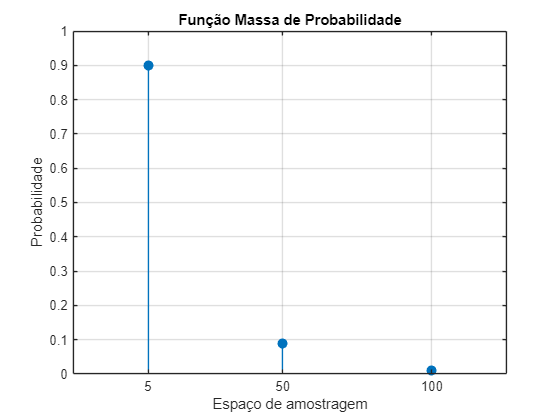

prob = [90/100, 9/100, 1/100];
% Criar a figura
figure;

% Gráfico da função massa de probabilidade
stem(Sb, prob, 'filled', 'MarkerSize', 7);
xlabel('Espaço de amostragem');
ylabel('Probabilidade');
title('Função Massa de Probabilidade');
xticks(Sb);
ylim([0 1]);
grid on;

(c) Determine a funcao de distribuicao acumulada de X, FX(x), e efetue a sua representacao grafica em Matlab.

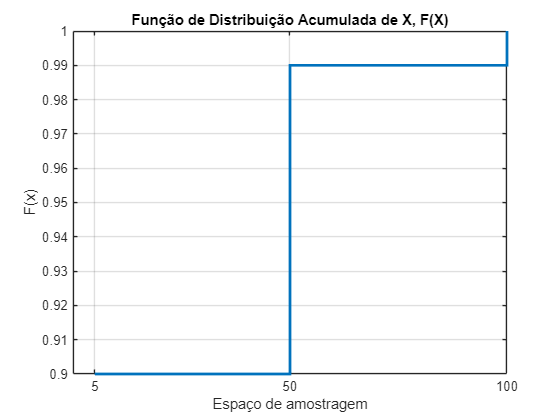

figure;
% Gráfico da função de distribuição acumulada
soma = cumsum(prob);
stairs(Sb, soma, 'LineWidth', 2);
xlabel('Espaço de amostragem');
ylabel('F(x)');
title('Função de Distribuição Acumulada de X, F(X)');
xticks(Sb);
grid on;

 3. Considere 4 lancamentos de uma moeda equilibrada. Seja X a variavel aleatoria representativa do numero de coroas observados nos 4 lancamentos. 

(a) Estime por simulacao a funcao massa de probabilidade pX(x) da variavel aleatoria X. 

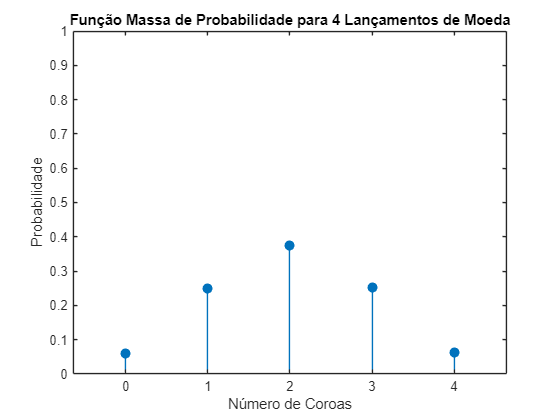

N = 1e5; 
% Espaço amostral para o número de coroas
S = 0:4; 
probs = zeros(1, length(S)); 

for value = S
    cont = 0; % Contador de coroas
    for sim = 1:N
        % Simular 4 lançamentos de uma moeda (1 para coroa, 0 para cara)
        flips = randi([0, 1], 1, 4); % 0 = cara, 1 = coroa
        numCoroas = sum(flips); 
        if numCoroas == value
            cont = cont + 1; 
        end
    end
    % Calcular a probabilidade
    probs(value + 1) = cont / N; 
end

figure;
stem(S, probs, 'filled', 'MarkerSize', 7);
xlabel('Número de Coroas');
ylabel('Probabilidade');
title('Função Massa de Probabilidade para 4 Lançamentos de Moeda');
xticks(S);
ylim([0 1]);

(b) Estime o valor esperado, a variancia e o desvio padrao de X com base em pX(x). 

(c) Identifique o tipo da distribuic¸˜ ao da vari´ avel aleat´ oria X e escreva a express˜ao te´ orica da respetiva func ¸˜ ao de probabilidade. 

(d) Calcule os valores te´ oricos da func ¸˜ ao massa de probabilidade de X e compare-os com os valores estimados por simulac ¸˜ ao obtidos em (a). 

(e) Calcule os valores te´ oricos de E[x] e de V ar(X) e compare-os com os valores obtidos em (b). 

(f) Com base nos valores te´ oricos da func ¸˜ao massa de probabilidade desta distribuic ¸˜ ao, calcule: i. a probabilidade de obter pelo menos 2 coroas; ii. a probabilidade de obter at´ e 1 coroa; iii. a probabilidade de obter entre 1 e 3 coroas.